# Simple Example

This example

## $\S$Introduction

Consider the following convolution problem, corresponding to the case with one MPS term and one receiver location:


$$d(t) = G(t)*w(t) = \int_{-\infty}^\infty G(t-\tilde t) w(\tilde t) \; d\tilde t$$


Here

- $d(t)$ = data at a single receiver as a function of time

- $G(t)$ = Green's function (at the receiver location) as a function of time

- $w(t)$ = source time function (for a single MPS term)

We make the following assumptions that will come into play in the discretization of the convolution integral.

- $w(t)$ is zero outside of the interval $[0, T]$

- $d(t)$ is measured over the same time interval $[0, T]$

- $G(t)$ is causal, i.e., $G(t)=0$ for $t<0$.

Given the finite support of $w(t)$, we have


$$G(t)*w(t) = \int_{0}^{T} G(t-\tilde t) w(\tilde t) \; d\tilde t$$


To compute a numerical approximation to the convolution problem, we introduce following uniform time grid, $\{t_k\}_{k=0}^{K-1}$

$t_k = k\Delta t$, $k=0,1,...,K-1$

where $\Delta t = T/(K-1)$. Discretizing the convolution integral using a midpoint rule, with intervals of length $\Delta t$ centered on grid points $t_k$, we obtain


$$d(t_i) \approx \Delta t \sum_{k=0}^_{K-1} G(t_i-t_k) w(t_k)$$


where indexes $i,k$ in the sum now play the role of $t,\tilde t$ in the integral. 

Remarks:

- Since $t_0=0$, and the data and source time functions are discretized over the same uniform time grid, it follows that $G(t_i-t_k) = G(t_{i-k+1})$.

- For $i> k$, $t_{i-k+1}<0$ and hence $G(t_{i-k+1})=0$ since $G(t)$ is causal. In practice, we define $G(t_j)$ for $j=-K+1,-K+2,...,K$, a total of $2K-1$ points.

Using matrix-vector notation, we have


$$\mathbf d = A \mathbf w$$


where, for $i,k=1,2,..., K$

- $\mathbf d\in\mathbb R^{K}$, with $d_i \approx d(t_i)$ 

- $\mathbf w\in\mathbb R^{K}$, with $w_k = w(t_k)$

- $A\in\mathbb R^{K\times K}$, with $[A]_{ik} = 0$ for $i> k$ and $[A]_{ik}= \Delta t\; G(t_{i-k+1})$ for $i\le k$

clear

% Defining time grid
K = 101; %number of time points on base grid
T = 100;
dt = T/(K-1);

t_grid = linspace(0,T,K); %base grid
t_grid_ext = linspace(-T+dt,T,2*K-1); %extended grid for plotting Green's function

## $\S$Green's Function

In practice, Green's functions are computed by numerically solving some wave equations with impulsive point sources. The resulting Green's functions are qualitatively rough, almost random looking. We use a random number generator to construct a fake Green's function with these qualitative properties. 

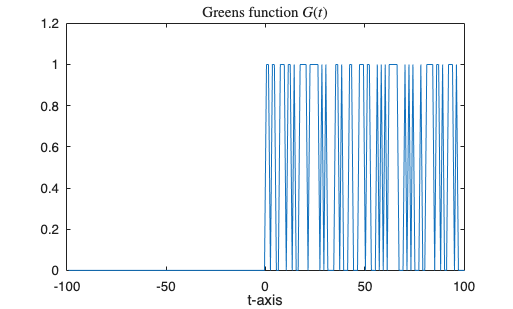

% Generating Green's function
rng('default') %fixing seeding so that the same random number is generated everytime
G = rand(K,1);
G = round(G);
G = [zeros(K-1,1); G]; %padding with zeros to extend domain of G

figure
plot(t_grid_ext,G)
title('Greens function $G(t)$','Interpreter','latex')
xlabel('t-axis')
ylim([0,1.2])

## $\S$Source Function

Unlike the Green's function, the source time function $w(t)$ will be relatively smooth. Here we use a common time signal used in seismology, the Ricker wavelet.

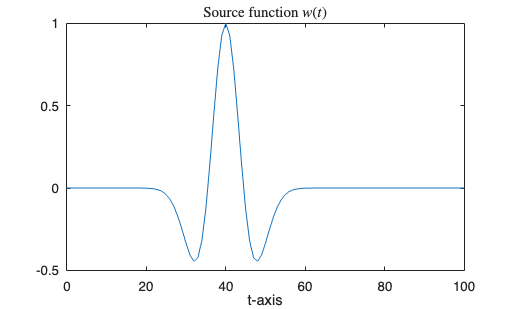

% Generating source time function
fpeak = 0.05; %peak frequency
tc = 40; %center point
w = RickerWave(t_grid,tc,fpeak);

figure
plot(t_grid,w)
xlabel('t-axis')
title('Source function $w(t)$','Interpreter','latex')

## $\S$Convolution Matrix

Note that $A$ is the matrix representation of our discretized convolution, and thus is referred to as a *convolution matrix*. An important property to note is that $A$ is a Toeplitz matrix in that


$$[A]_{ij} = c_{i-j}$$


for some constants $c_{k}$; in our case $c_k = \Delta t \; G(t_k)$. 

We can make use of the `toeplitz()` MATLAB function to construct explicitly our convolution matrix. To do so, we require the first column and first row of the matrix.


$$A(:,1) = \Delta t\; \Big[ G(t_1), \; G(t_2), \; \cdots, \; G(t_K) \Big]^T$$



$$A(1,:) = \Delta t \; \Big[ G(t_1), \; G(t_0), \; \cdots, \; G(t_{-K+1})\Big]$$


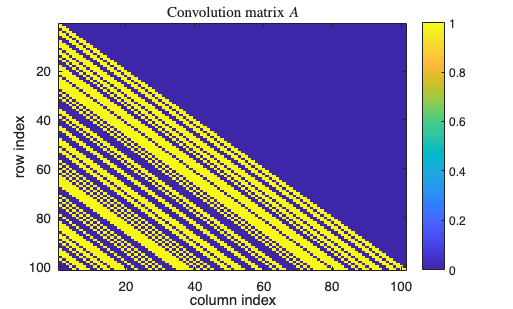

A_row = dt*G(K:-1:1); %first row of
A_col = dt*G(K:end);
A = toeplitz(A_col,A_row);

figure
% spy(F)
imagesc(A)
xlabel('column index')
ylabel('row index')
colorbar
title('Convolution matrix $A$','Interpreter','latex')

## $\S$Computing Data

With the constructed convolution matrix $A$, we compute the data vector $\mathbf d = A \mathbf w$. 

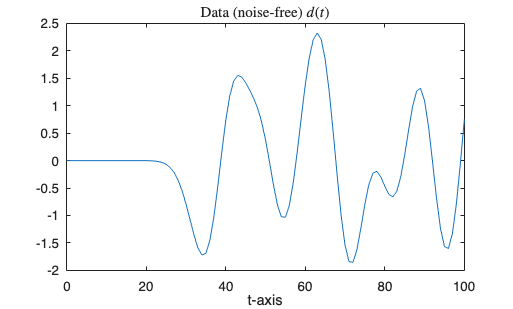

d = A*w;
figure
plot(t_grid,d)
xlabel('t-axis')
title('Data (noise-free) $d(t)$','Interpreter','latex')

## $\S$Naive Deconvolution

The inverse problem consists of solving for $\mathbf w$ given $A$ and $\mathbf d$. The tempting thing to do would be to simply solve the system of equations $A\mathbf w = \mathbf d$. Indeed, if we did so with the given data then we would recover an almost perfect $\mathbf w$.

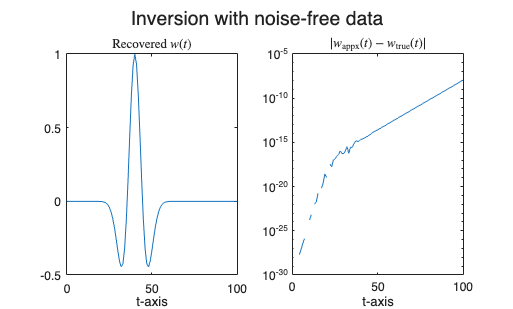

w_nf = A\d;

figure
sgtitle('Inversion with noise-free data')

subplot(1,2,1)
plot(t_grid,w_nf)
xlabel('t-axis')
title('Recovered $w(t)$','Interpreter','latex')

subplot(1,2,2)
semilogy(t_grid,abs(w_nf-w))
xlabel('t-axis')
title('$|w_{\rm appx}(t)-w_{\rm true}(t)|$','Interpreter','latex')

The results above are too good to be true/practical for a couple of reasons:

- The same convolution matrix used to create the data is used in the inversion.

- Data is noise free.

Let us reattempt the inversion with a slightly noisy data.

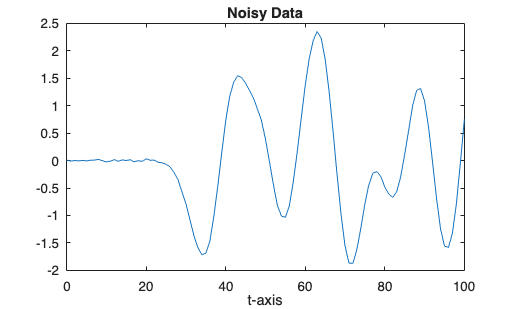

noise = randn(size(d))*max(abs(d))*0.005;
d_noisy = d+noise;

figure
plot(t_grid,d_noisy)
xlabel('t-axis')
title('Noisy Data')

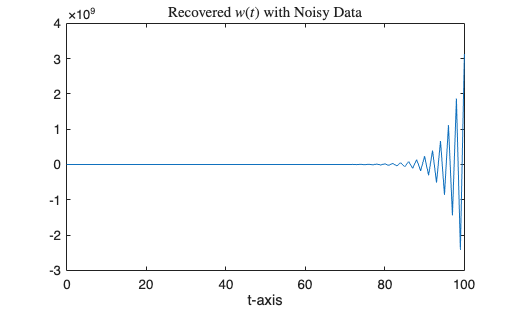

% Solving for source using noisy data
w_naive = A\d_noisy;

figure
plot(t_grid,w_naive)
xlabel('t-axis')
title('Recovered $w(t)$ with Noisy Data','Interpreter','latex')

## $\S$SVD Analysis

At last, our previous results were indeed too good to be true. The process of solving for $\mathbf w$ is too sensitive to noise; we refer to the inverse problem as being ill-conditioned. In fact, ill-conditioning of the inverse problem stems from the large condition number of the convolution matrix $A$.

cond(A)

ans = 9.8490e+12

Let $\mathbf d = \tilde{\mathbf d} + \varepsilon$ denote the noisy data where $\tilde{\mathbf d}$ is the noise-free data and $\varepsilon$ is the noise vector. Assuming $A$ is invertible, let $\tilde{\mathbf w} = A^{-1}\tilde{\mathbf d}$ denote the true solution in the noise-free case. Similarly, let $\mathbf w = A^{-1}\mathbf d$ denote the noisy solution, that is, the solution obtained from using the noisy data. Using the SVD of $A$, we have


$$\|\mathbf w-\tilde{\mathbf w}\|^2 =  \| A^{-1}\varepsilon\|^2 =  \sum_{i=1}^n \left(\frac{\mathbf u_i^T \varepsilon}{\sigma_i} \right)^2$$


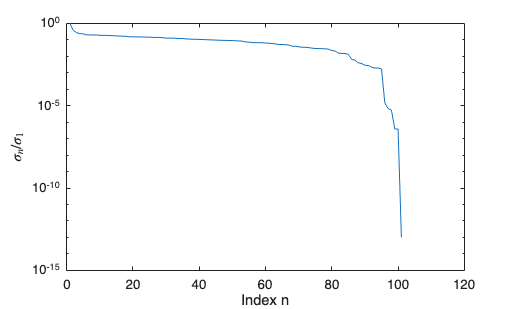

[U,S,V] = svd(A);
s_vals = diag(S);

figure
semilogy(s_vals/s_vals(1))
xlabel('Index n')
ylabel('$\sigma_n/\sigma_1$','Interpreter','latex')

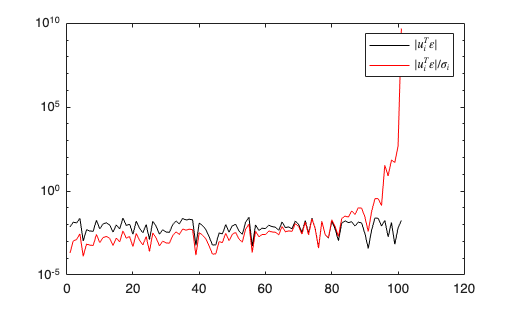

figure
semilogy(abs(U'*noise),'-k')
hold on
semilogy(abs(U'*noise)./s_vals,'-r')
legend('$|u_i^T \varepsilon|$','$|u_i^T \varepsilon|/\sigma_i$','Interpreter','latex')